FULL EV DRIVE MODEL SCRIPT

Load Model

clear
clc
close all
mdl1='model_EV_pt1';
open(mdl1)
tstop=30;%simulation time

Battery

Voc=360; %open circuit voltage
Rbatt=0.0215; %battery resistance
%Energy Capacity
E=50000; %WHr
%Amp-hr rated
Q=E/Voc;
%amp-hr used
Qo=0.2*Q;
%state of charge
SOC_max=80;
SOC_min=20;
%duty cycle
D=1;
%D=0.4889;

PMDC

Km=0.22; %motor constant
Ra=0.015; %armature resistance
La=0.025; % inductance
J=0.01; %motor inertia
GR=9; %gear ratio

Vehicle model

% TESLA Model 3 RWD
M=4250*0.4535924; %Kg
F0=37.170*0.4535924*9.81;
F1=0.0470*0.4535924*9.81*(3600/1609.34);
F2=0.0144*0.4535924*9.81*(3600/1609.34)^2;
r_wheel=0.334;% m
xdot_o=0;

slope

slope=0;

simulation 

sim(mdl1)

Plots and Figures

k=length(logsout{1}.Values.Data)

k = 30016

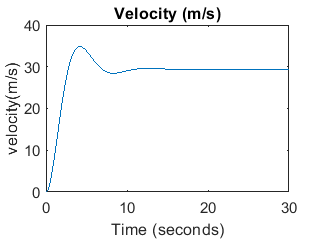

% velocity(m/s) vs time
plot(logsout{18}.Values)
title('Velocity (m/s)')
ylabel('velocity(m/s)')

v_ss=logsout{18}.Values.Data(k)

v_ss = 29.4279


%velocity(mph)vs time
plot(logsout{19}.Values)
title('v_mph')
ylabel('v_mph')
V_mph_ss=logsout{19}.Values.Data(k)

V_mph_ss = 65.8285

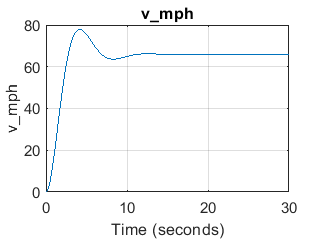

grid on

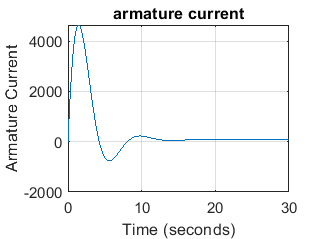


%PMDC Armature Current
plot(logsout{2}.Values)
ylabel('Armature Current')
title('armature current')
grid on

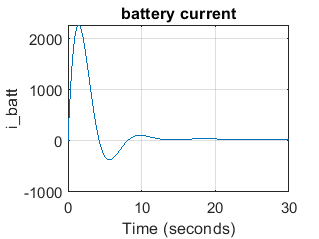


%battery current
plot(logsout{3}.Values)
ylabel('i_batt')
title('battery current')
grid on

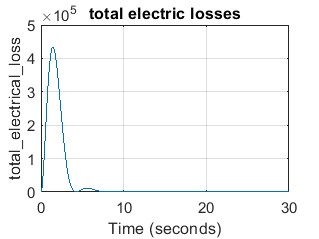


%total electrical losses
plot(logsout{1}.Values)
grid on
title('total electric losses')

total_electric_loss_ss=logsout{1}.Values.Data(k)

total_electric_loss_ss = 119.5238